# Sensors Hardware Calibration

## Introduction

The goal is to generate the appropriate values to transform bit input from the analog sensor block to milliampere, before filtering:

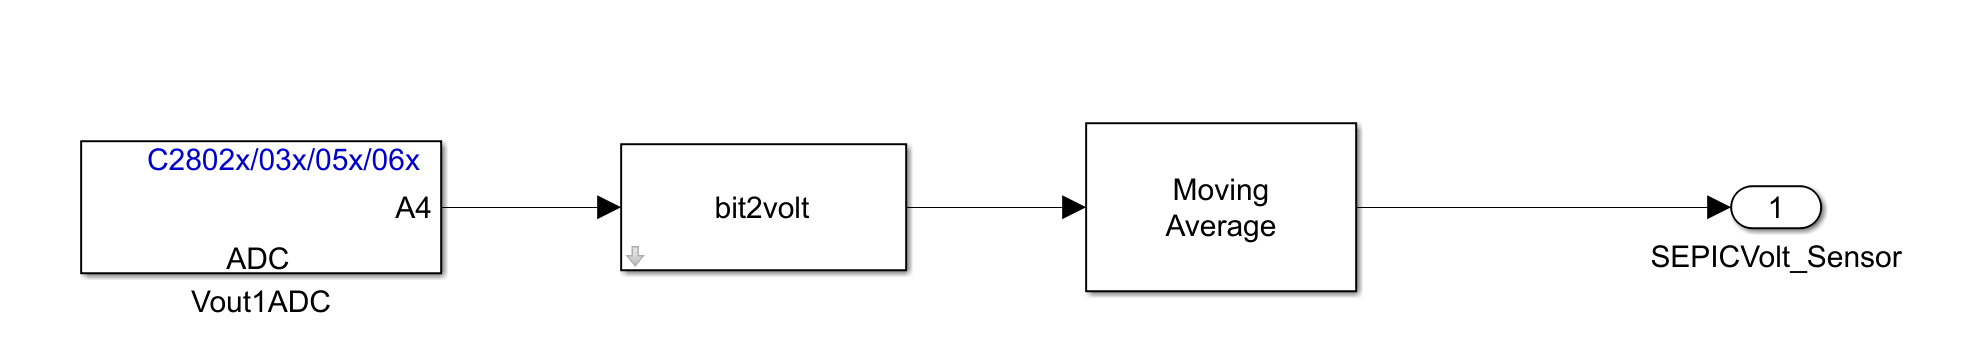

the bit2volt block is a custom block created to translate bit information to a physical unit (in this case volt) for easier understanding of sensor feedback. It has three parameters to implement following transformation:

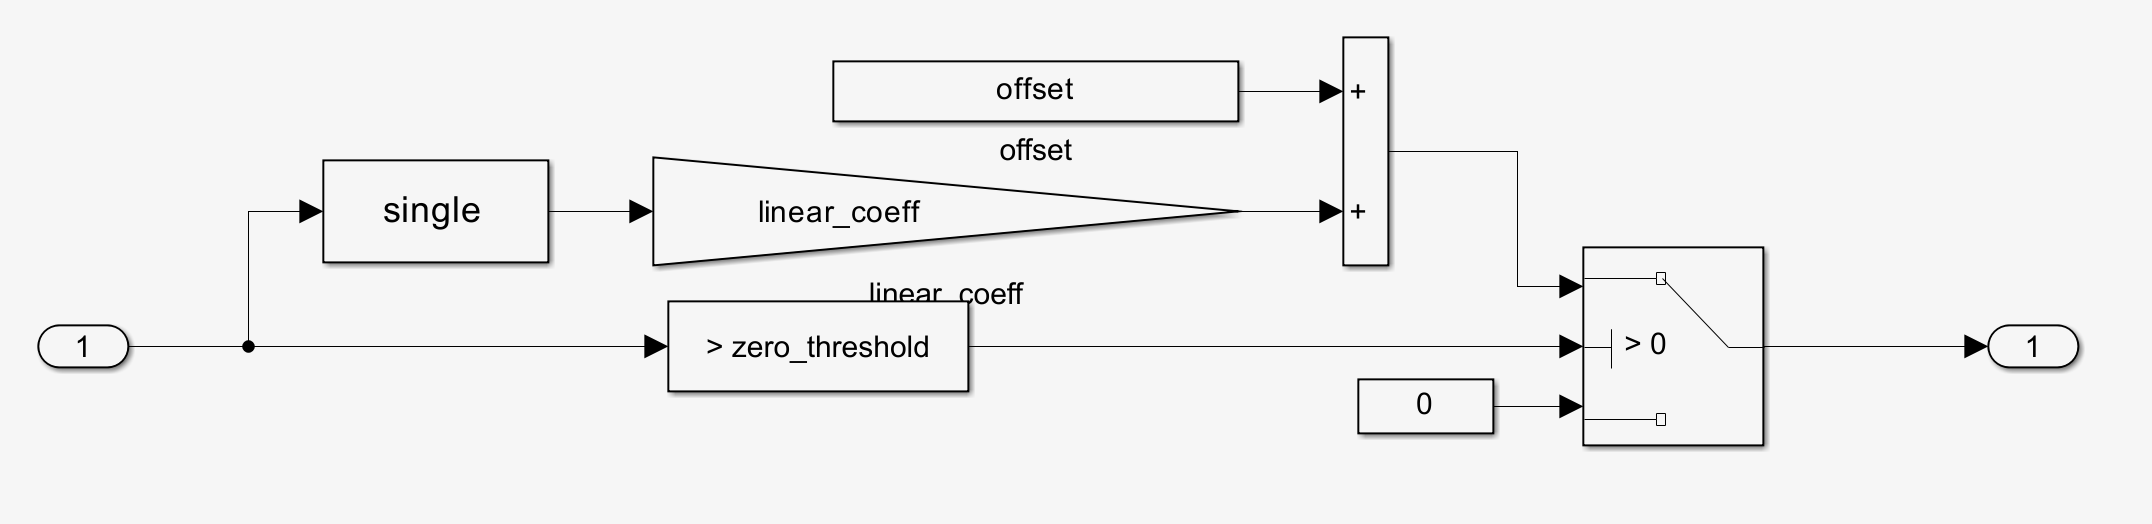

- The linear coefficient to multiply the driver output directly

- an offset to compensate sensor bias

- a zero_threshold to compensate noise when the sensor should send out 0, but instead is sending out a couple of bit of white noise

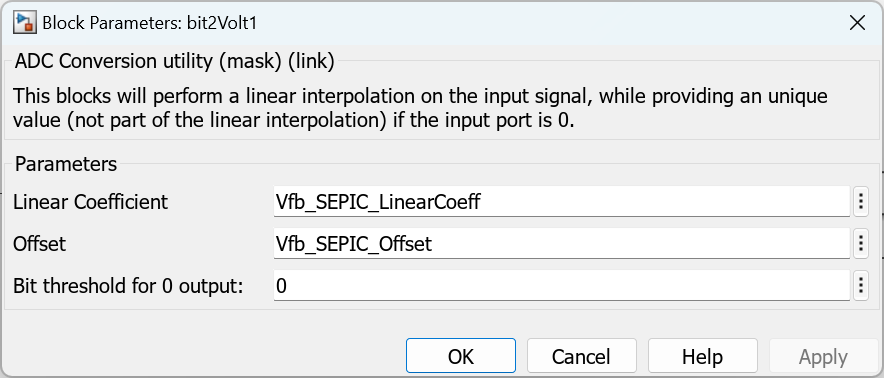

## Workflow 1: fit measurement to linear model (voltage sensor example)

The SEPIC DCDC converter was stimulated using a stairs step from 0 to 77% Duty Cycle

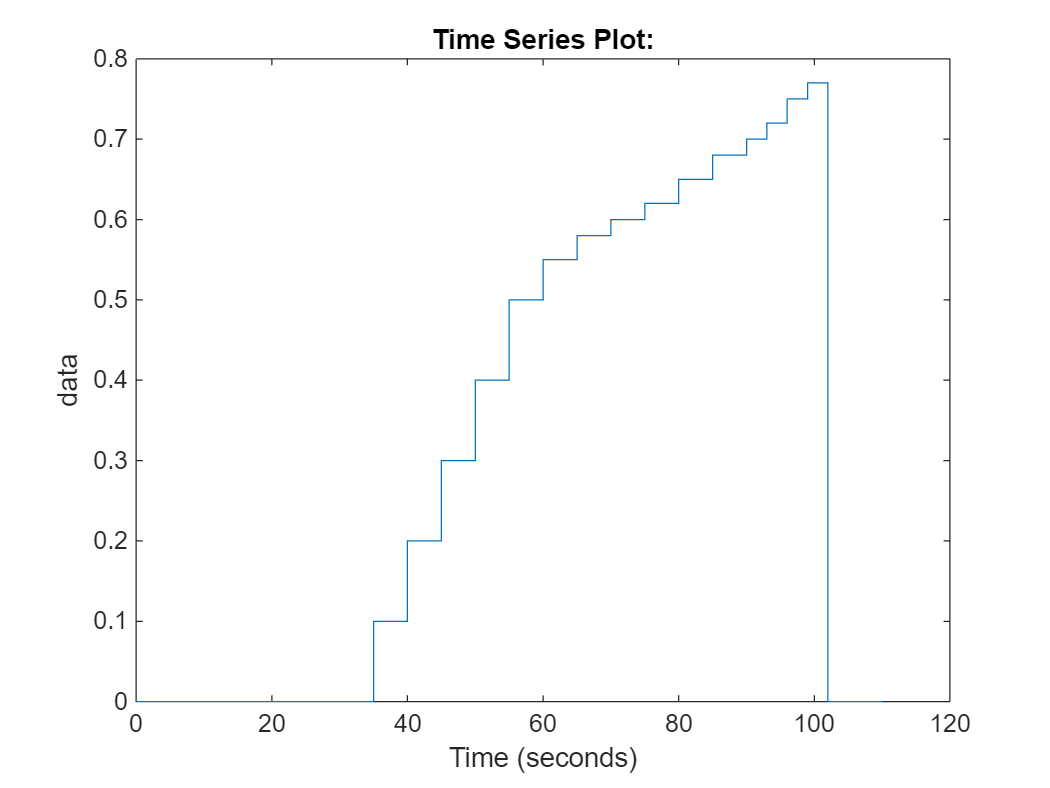

load OpenLoop_realHW_HarnessInputs.mat
plot(SensorCalibration{1}.Values)

Measured Voltage at that Duty Cycle:

Vmeas = [0 2.03 3.26 4.87 7.58 11.40 13.92 15.71 17.04 18.48 21.0 23.9 26.1 28.5 32.7 35.8];
DC_in = [0 0.1 0.2 0.3 0.4 0.5 0.55 0.58 0.6 0.62 0.65 0.68 0.7 0.72 0.75 0.77];

The response read from the ADC pinout of the TI C2000:

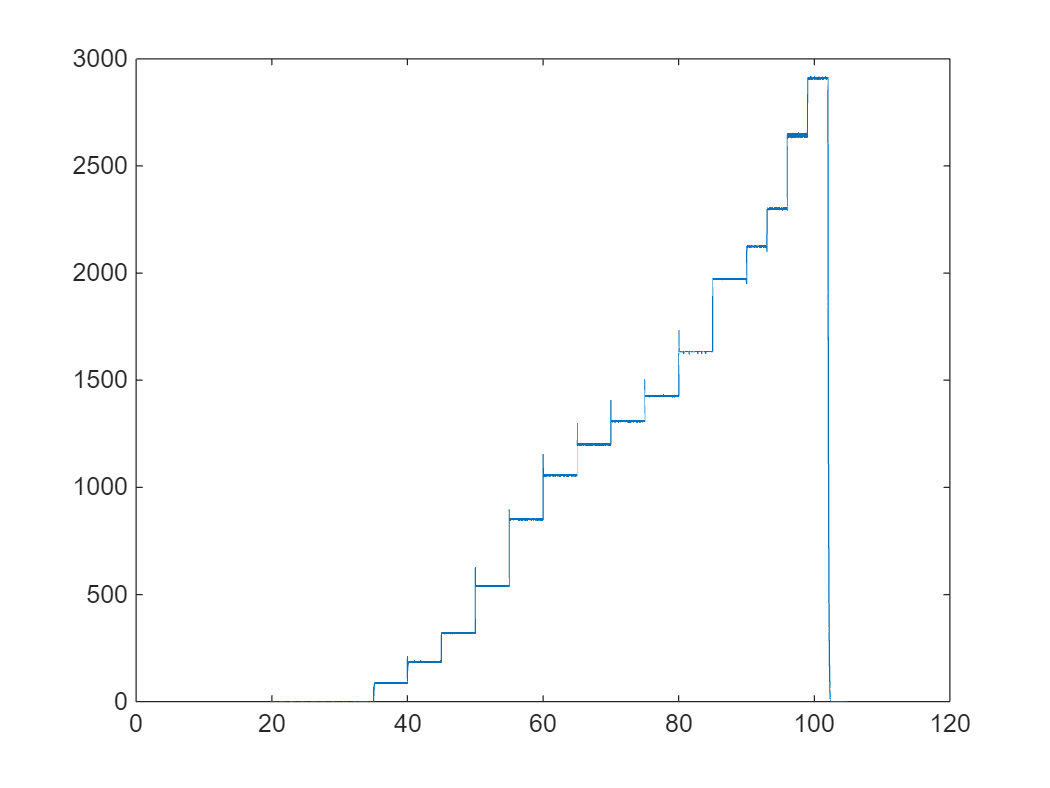

load SEPICVoltageSensorCalibration.mat
plot(VoltPinOut.time,VoltPinOut.data)

As an example: let's zoom in at the end of a settling time (between 47 and 49.8, step happens at 50 sec:

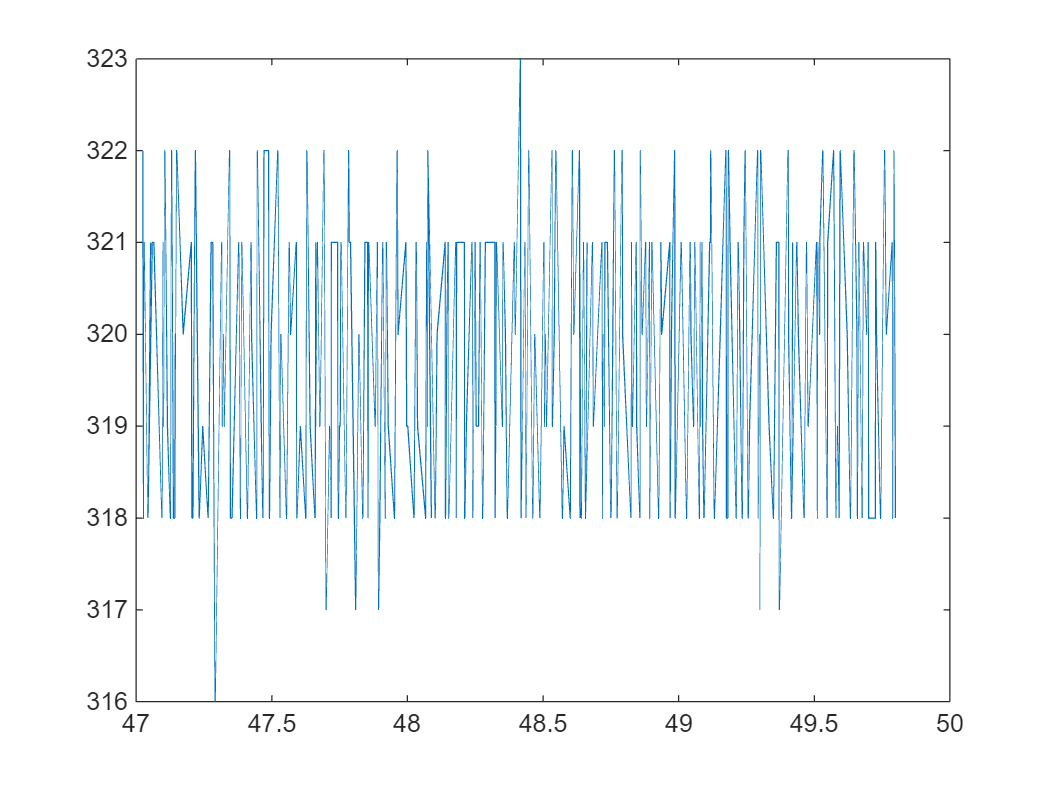

test =VoltPinOut.data(VoltPinOut.time >47 & VoltPinOut.time <49.8);
testtime = VoltPinOut.time(VoltPinOut.time >47 & VoltPinOut.time <49.8);
plot(testtime,test)


mean(test)

ans = 319.7379

clear test testtime


Let's now smooth the data and iterate over the stimulation factor, averaging over the last 2.8 sec on the settling time:

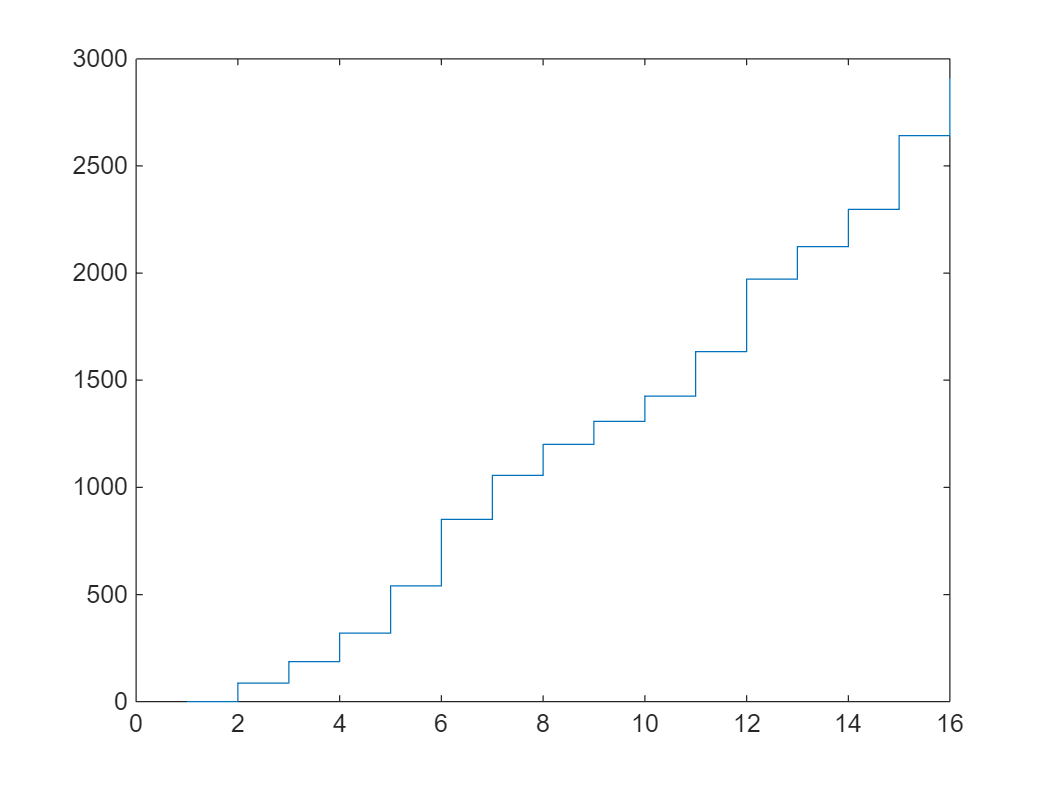

deltaTime = 2.8;
threshold = 0.2;
PinOutAvg = zeros(size(Vmeas));
for k=2:length(Vmeas)+1
    UpperLimit = SensorCalibration{1}.Values.Time(k)-threshold;
    LowerLimit = UpperLimit-deltaTime;
    if k>1
        PinOutAvg(k-1)=mean(VoltPinOut.data(VoltPinOut.time > LowerLimit & VoltPinOut.time <UpperLimit));
    end
end
stairs(PinOutAvg)

If we examine the relationship bit vs voltage, we notice a linear trend (hence the linear model proposed at the introduction):

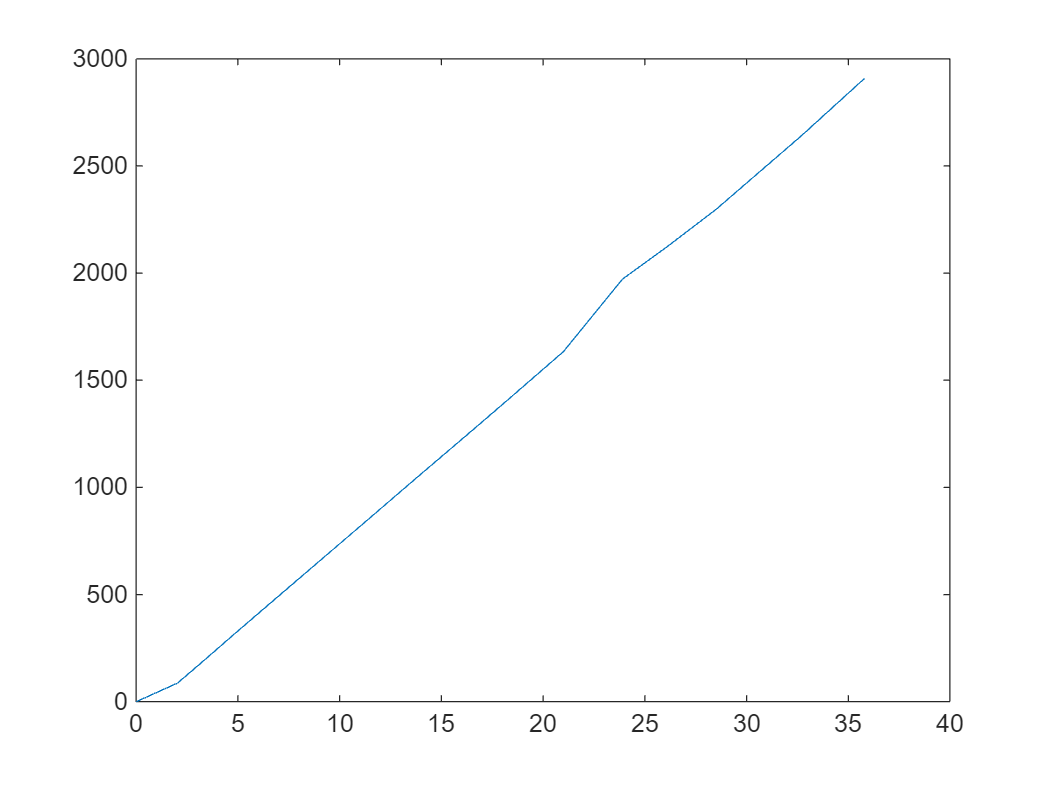

plot(Vmeas,PinOutAvg)


clear deltaTime threshold UpperLimit LowerLimit k

Now we can fit the data to a linear function:

Bit2Volt_FitObject = fit(PinOutAvg', Vmeas', 'poly1')

Bit2Volt_FitObject =      Linear model Poly1:
     Bit2Volt_FitObject(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.01201  (0.01177, 0.01226)
       p2 =       0.965  (0.5823, 1.348)

Test input vector:

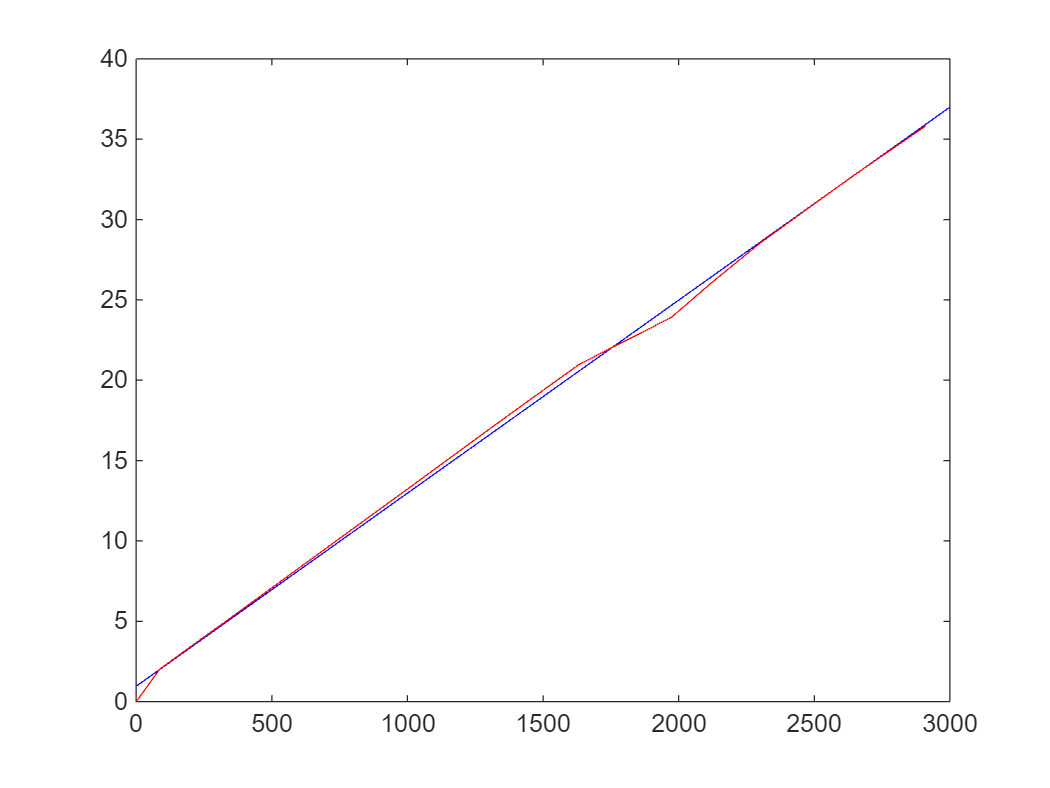

testPinInput=[0:100:3000];

testVOut = Bit2Volt_FitObject(testPinInput);
plot(testPinInput,testVOut,'b',PinOutAvg,Vmeas,'r')

## Workflow 2: retrieve linear model from schematics

If we look at the voltage sensor schematics:

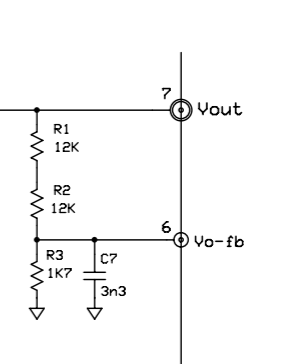

We see that the output Vo_fb is connected through a voltage divider to V_out.

The relationship between V_out and Vo_fb is following:

R1 = 12e3;
R2 = R1

R2 = 12000

R12 = R1+R2

R12 = 24000


R3 = 1.7e3;

VoltRef= 3.3;

Vo_fb = R3/(R12+R3)*Vmeas;


Let's transform the measured voltage in bit signal, relative to the internal reference of 3.3 Volt

bit2voltCoefficient = VoltRef/2^12*(R12+R3)/R3

bit2voltCoefficient = 0.0122

SimPinOut = int16(Vo_fb/VoltRef * 2^12)

SimPinOut = 1×16 int16 row vector
      0    167    268    400    622    936   1143   1290   1399   1517   1724   1962   2143   2340   2685   2939


Plotting again simulation + 2 results:

plot(testPinInput,testVOut,'b',PinOutAvg,Vmeas,'r',SimPinOut,Vmeas,'g');

So in the end we decided to use the linear model, but in the Simulink model it will be implemented so that with 0 input there is a 0 output.

clear SimPinOut testVOut PinOutAvg testPinInput R1 R12 R2 R3 VoltRef Vo_fb ans Bit2Volt_FitObject bit2voltCoefficient DC_in SensorCalibration Stairs_Steps Stairs_Steps_10sec Step_after_Initialization Vmeas VoltPinOut


## Saving coefficients as software tunable parameters:

Let's create the necessary parameters:

myDictionaryObj = Simulink.data.connect('LocalDataD_TIC2000_F28069_Interfaces.sldd');

myDictionaryObj.Vfb_SEPIC_LinearCoeff.Value = single(Bit2Volt_FitObject.p1);
myDictionaryObj.Vfb_SEPIC_Offset.Value = single(Bit2Volt_FitObject.p2);
clear Bit2Volt_FitObject

These others have the offset calculated from the circuit diagram/measurements, for LED current sensor:

Rshunt = 0.25; % Ohm
GainAmp = 12; %[-]
Vref = 3.3; % V
ADCconv = 2^12; % bit
MilliAmpere = 1e3;

myDictionaryObj.Ifb_LED_LinearCoeff.Value =single(Vref/ADCconv/Rshunt/GainAmp*MilliAmpere);
myDictionaryObj.Ifb_LED_Offset1.Value=single(7);%mA
myDictionaryObj.Ifb_LED_Offset2.Value=single(9);%mA
myDictionaryObj.Ifb_LED_Offset3.Value=single(5);%mA
myDictionaryObj.Ifb_LED_Offset4.Value=single(1);%mA
myDictionaryObj.Ifb_LED_Offset5.Value=single(16);%mA
myDictionaryObj.Ifb_LED_Offset6.Value=single(2);%mA
clear Vref GainAmp Rshunt ADCconv MilliAmpere

SEPIC current sensor:

Rshunt = 0.1; % Ohm
GainAmp = 8.2; %[-]
Vref = 3.3; % V
ADCconv = 2^12; % bit
MilliAmpere = 1e3;

myDictionaryObj.Ifb_SEPIC_LinearCoeff.Value=single(Vref/ADCconv/Rshunt/GainAmp*MilliAmpere)
myDictionaryObj.Ifb_SEPIC_Offset.Value = single(77)
clear Vref GainAmp Rshunt ADCconv MilliAmpere


And finally for the power supply voltage sensing:

myDictionaryObj.Vin_Supply_LinearCoeff.Value =  single(3.3/2^12*(47e3/3+820)/820);

Saving data dictionary:

% saveChanges(myDictionaryObj)
